## Part 1:

### 1)

#### a.

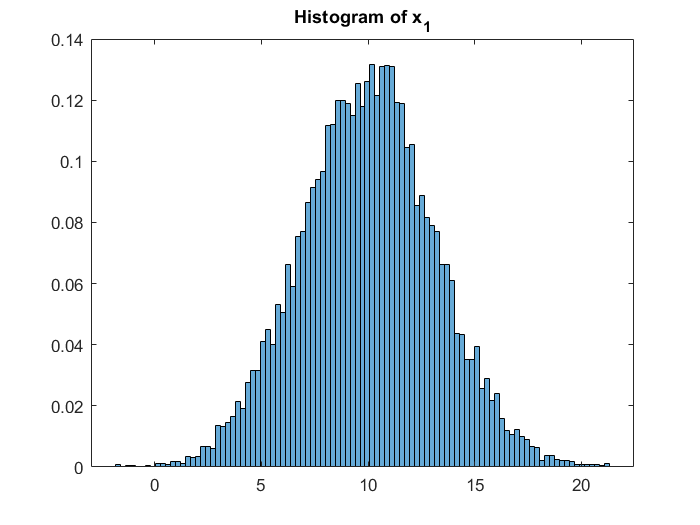

x1 = sqrt(10) * randn(1, 10000) + 10;
step = (max(x1) - min(x1)) / 99;
edges = min(x1):step:max(x1);
histogram(x1, edges, 'Normalization', 'pdf')
title("Histogram of x_1")

#### b. 

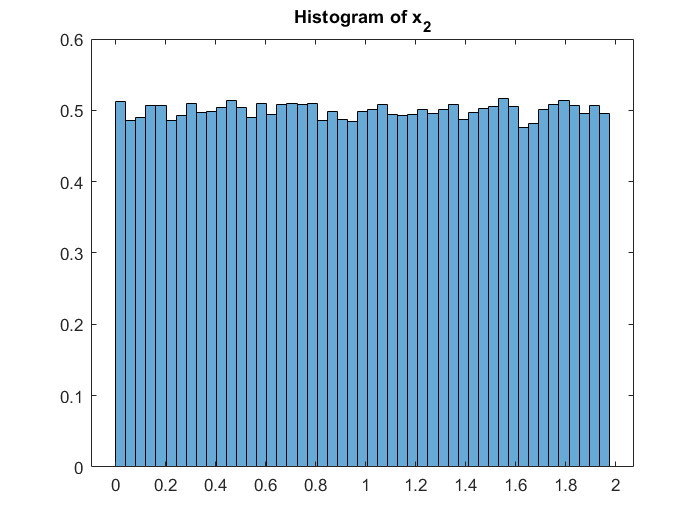

x2 = 2 * rand(1, 100000);
x2_shifted = [x2(100000), x2(1:99999)];
x3 = x2 + x2_shifted;
step = (max(x3) - min(x3)) / 99;
edges = min(x2):step:max(x2);
histogram(x2, edges, 'Normalization', 'pdf')
title("Histogram of x_2")

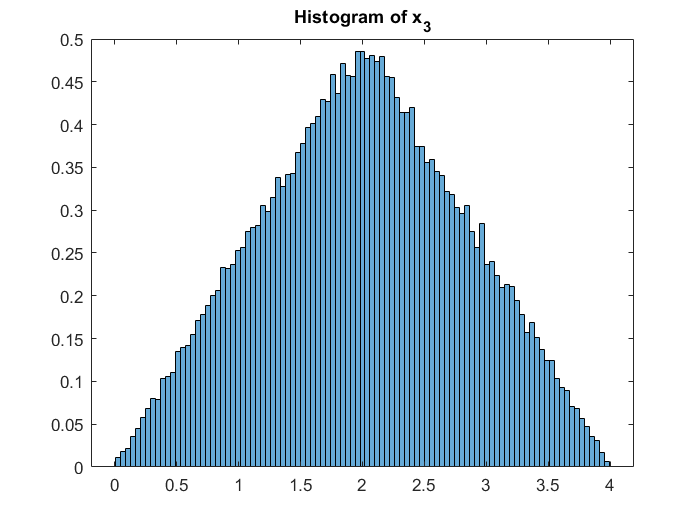

edges = min(x3):step:max(x3);
histogram(x3, edges, 'Normalization', 'pdf')
title("Histogram of x_3")

#### As shown in the figure, we can see that histogram of x3[n] is equal to the convolution of histogram of x2[n] and x2[n-1]. 

#### Elements of x2[n] are independent, so x2[n] is independent from x2[n-1]. If we assume x2 as x and x2[n-1] as y, then because x and y are independent x+y that is x3 has the distribution that is equal to the convolution of the ditribution of x and y.

#### c.

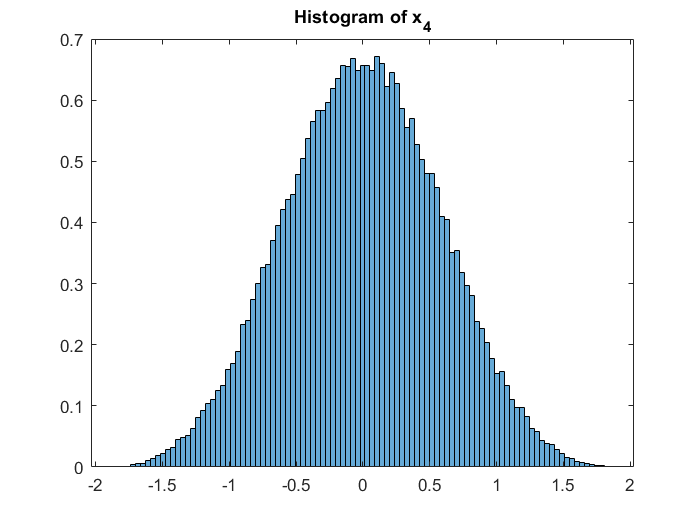

x4 = zeros(1, 100000);
for i = 1:4
    x4 = x4 + rand(1, 100000) - 0.5 * ones(1, 100000);
end
step = (max(x4) - min(x4)) / 99;
edges = min(x4):step:max(x4);
histogram(x4, edges, 'Normalization', 'pdf')
title("Histogram of x_4")

#### From previous part we know that y1 + y2 and y3 + y4 have triangle distribution. Now we can assume y1 + y2 as x and y3 + y4 as y, so the distribution of x + y is equal to the convolution of 2 triangle distributions that validates histogram of x4.

#### According to the central limit theorem, as the number of independent random variables added together increased, total distribution is more compatible with normal distribution.

### 2)

#### a.

x = [-2, 4, 3, -6, 5, -1, 8];
y = dwnsmpl(x, 2)

y =     -2     3     5     8


#### Function code is at the end of the file.

#### b.

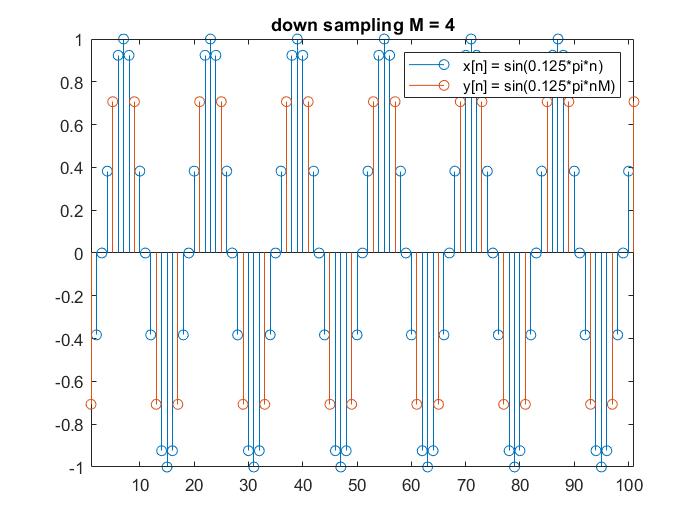

n = -50:50;
M = 4;
x = sin((0.125*pi).*n);
y = dwnsmpl(x, M);
y_ = zeros(1, length(x));
for i = 1:M:length(x)
    y_(i) = y((i - 1)/M + 1);
end

stem(x)
hold on;
stem(1:M:length(x), y)
title('down sampling M = 4')
hold off;
legend({'x[n] = sin(0.125*pi*n)', 'y[n] = sin(0.125*pi*nM)'})
axis tight

#### c.

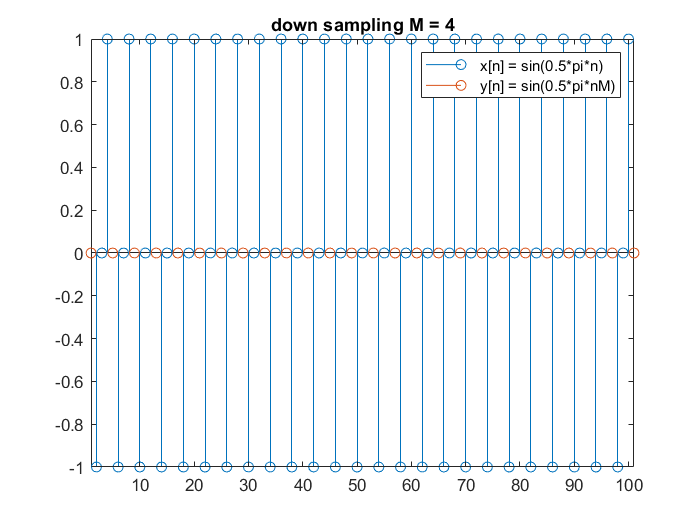

n = -50:50;
M = 4;
x = sin((0.5*pi).*n);
y = dwnsmpl(x, M);
y_ = zeros(1, length(x));
for i = 1:M:length(x)
    y_(i) = y((i - 1)/M + 1);
end

stem(x)
hold on
stem(1:M:length(x), y)
hold off
title('down sampling M = 4')
legend({'x[n] = sin(0.5*pi*n)', 'y[n] = sin(0.5*pi*nM)'})
axis tight

### 3)

#### a.

#### Function code is at the end of the file.

#### b.

x = [-2, 3, 5, 8];
y = upsmpl(x, 2)

y =     -2     0     3     0     5     0     8


#### As the output shows the function works!

## Part 2:

### 1)

#### a.

#### Assuming y[-1] = y[-2] = 0.

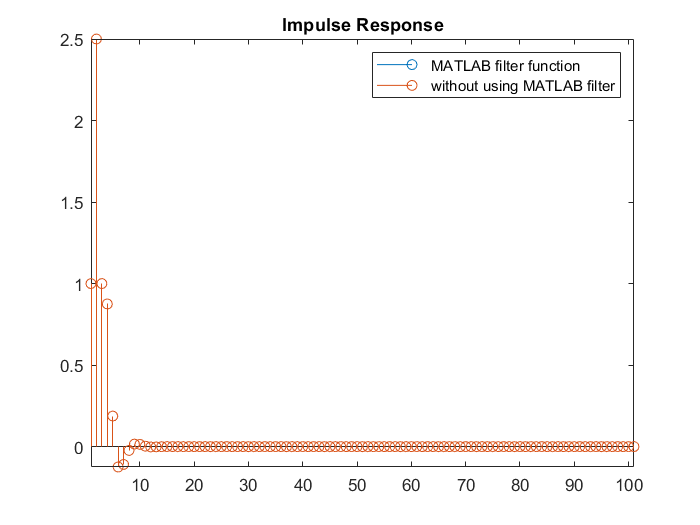

h = zeros(1, 103);
x = zeros(1, 101);
x(1) = 1;
x(2) = 2;
x(4) = 1;
for i = 3:103
    h(i) = 0.5*h(i-1) - 0.25*h(i-2) + x(i - 2);
end

b = [1 2 0 1];
a = [1 -0.5 0.25];
delta = [1 zeros(1, 100)];
h_filter = filter(b, a, delta);

stem(h_filter)
hold on
stem(h(3:103))
hold off
axis tight
title('Impulse Response')
legend({'MATLAB filter function', 'without using MATLAB filter'})

#### b.

#### We have the impulse response function so, we use convolution to calculate the output.

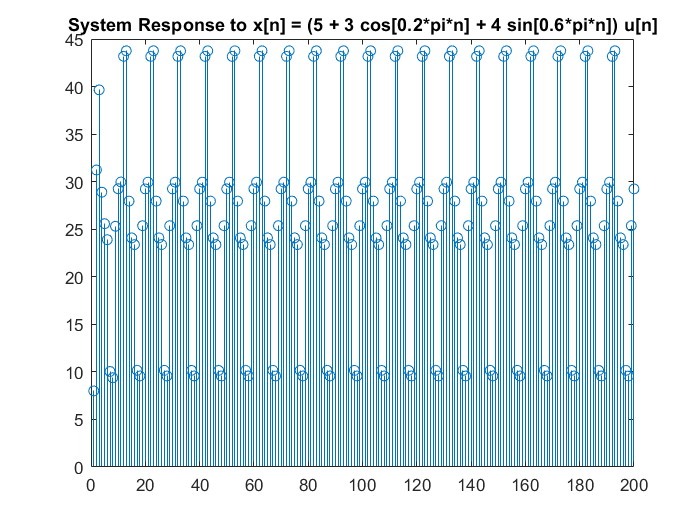

x = 5 * ones(1, 201) + 3 * cos((0.2*pi).*(0:200)) + 4 * sin((0.6*pi).*(0:200));
y = conv(h(3:103), x);

stem(y)
axis([0 200 0 45])
title('System Response to x[n] = (5 + 3 cos[0.2*pi*n] + 4 sin[0.6*pi*n]) u[n]')

### 2)

#### a.

#### Function code is at the end of the file.

#### b.

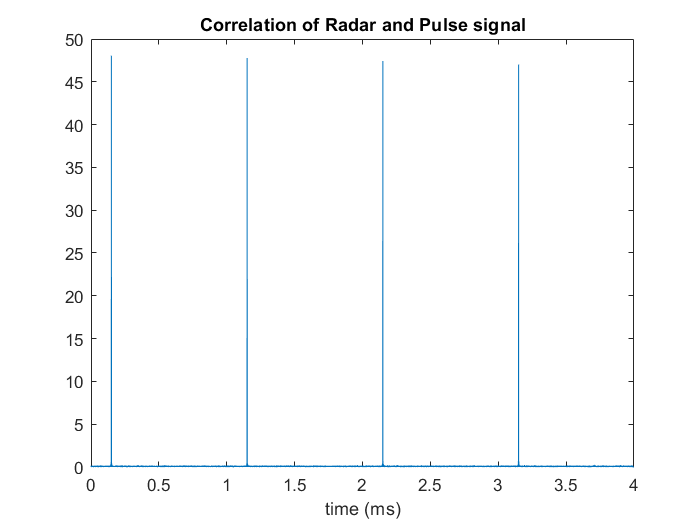

radar = struct2array(load('radar.mat'));
pulse = struct2array(load('pulse.mat'));
rp = corr_m(radar, pulse);
t = linspace(0, 4, 10^6);
plot(t, abs(rp))
title('Correlation of Radar and Pulse signal')
xlabel('time (ms)')

#### According to the figure of correlation of radar and pulse signal:

#### 
$$\tau =\frac{37501}{250\times {10}^6 }=150\ldotp 004\;\mu s\to R=22\ldotp 50\;\mathrm{Km}$$


#### By measuring the interval between 2 adjacent peaks:


$$T=\frac{250000}{250\times {10}^6 }=1\ldotp 00\;\mathrm{ms}\to \;\;\;\mathrm{periodicity}\;\mathrm{of}\;\mathrm{the}\;\mathrm{pulse}$$


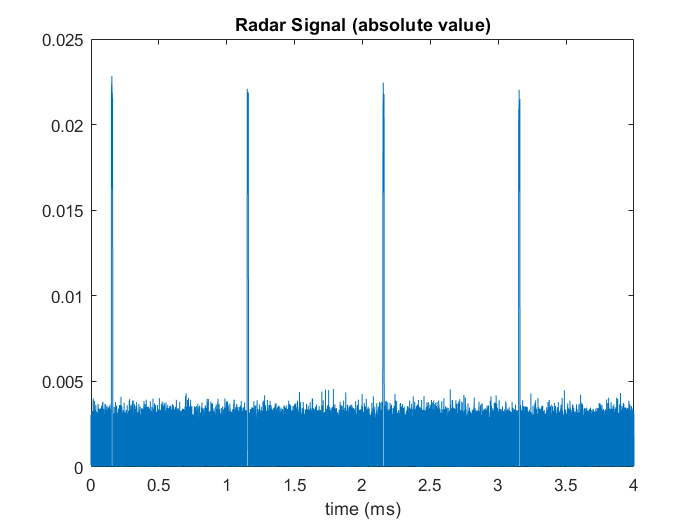

plot(t, abs(radar))
title('Radar Signal (absolute value)')
xlabel('time (ms)')

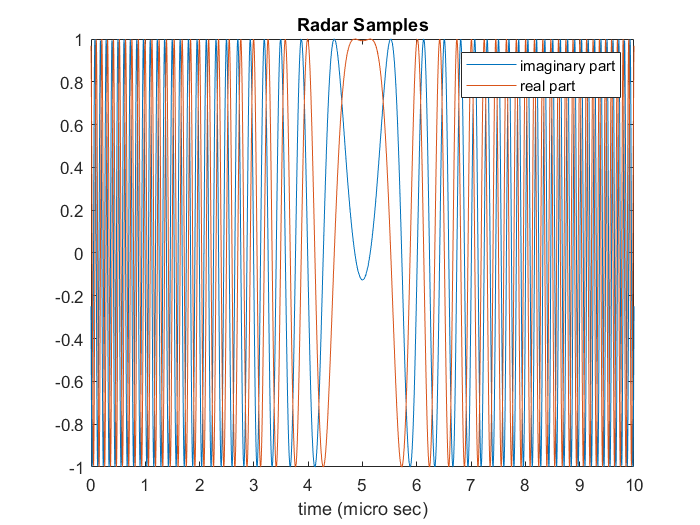


t = linspace(0, 10, 2500);
plot(t, imag(pulse))
hold on
plot(t, real(pulse))
hold off
title('Radar Samples')
xlabel('time (micro sec)')
legend({'imaginary part', 'real part'})

## Part 3:

### 1)

#### a.

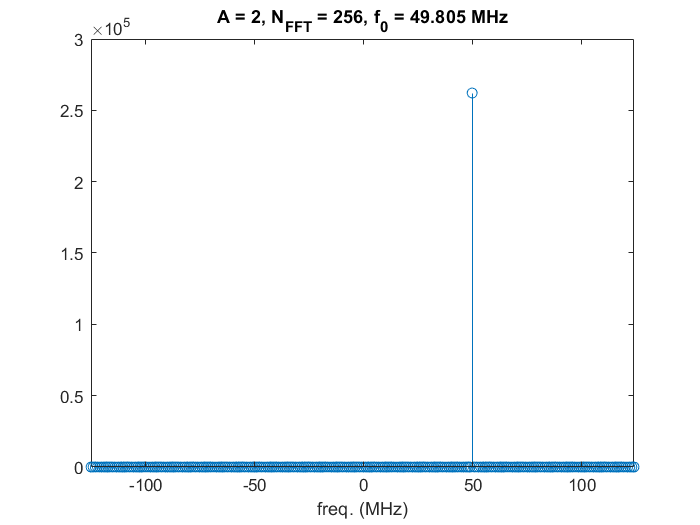

fs = 250*10^6;
ts = 1/fs;
n_fft = 256;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft));
stem(freq, abs(Xf).^2)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 256, f_0 = 49.805 MHz')

#### b.

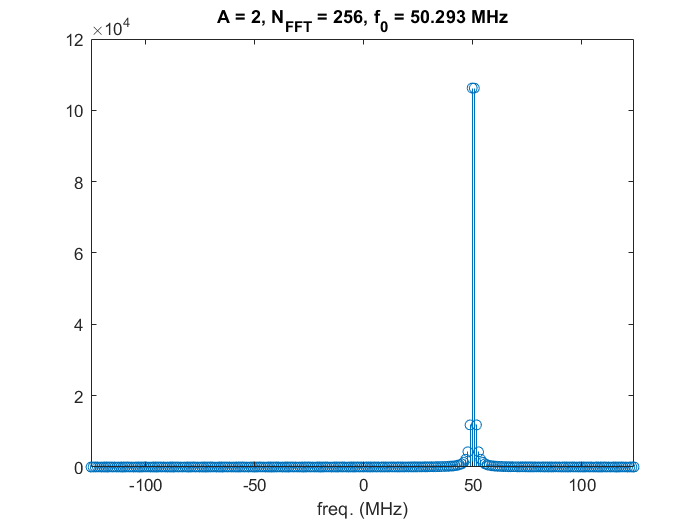

fs = 250*10^6;
ts = 1/fs;
n_fft = 256;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*51.5/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft));
stem(freq, abs(Xf).^2)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 256, f_0 = 50.293 MHz')

#### c.

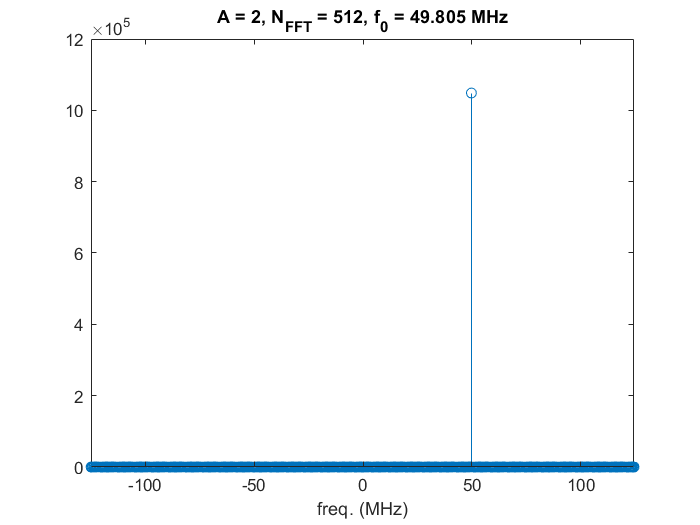

fs = 250*10^6;
ts = 1/fs;
n_fft = 512;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft));
stem(freq, abs(Xf).^2)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 512, f_0 = 49.805 MHz')

#### d.

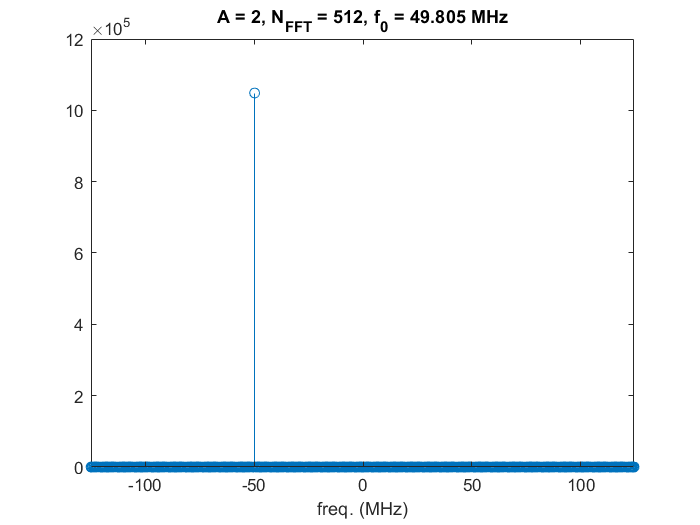

fs = 250*10^6;
ts = 1/fs;
n_fft = 512;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = -250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft));
stem(freq, abs(Xf).^2)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 512, f_0 = 49.805 MHz')

#### e.

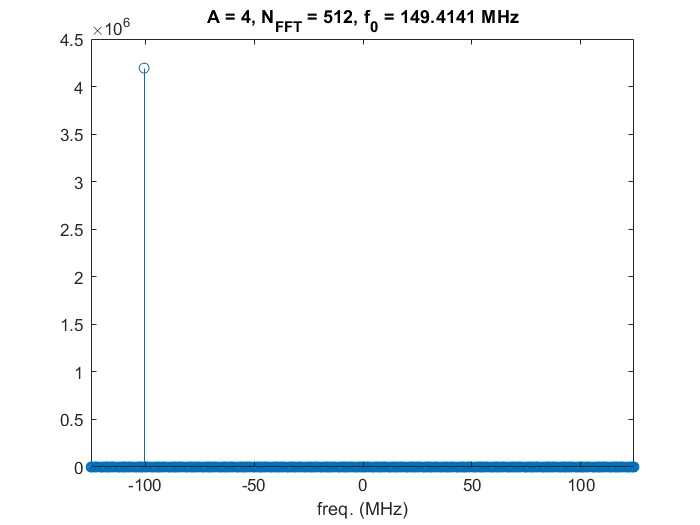

fs = 250*10^6;
ts = 1/fs;
n_fft = 512;
A = 4;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*153/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft));
stem(freq, abs(Xf).^2)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 4, N_F_F_T = 512, f_0 = 149.4141 MHz')

#### d.

#### 
$$\frac{N_{\mathrm{FFT}} \times T_s \;}{f_0 }=\left\lbrace \begin{array}{c}
51\\
51\ldotp 5\\
102\\
-102\\
306
\end{array}\right.$$


#### The calculated ratios above shows that the x-axis of the frequency plot cannot have exact value of f0 in part b (f0 is not an integer factor of the duration of one frame of the FFT), as we saw in figures. Instead, the nearest adjacent frequencies will appear. Therefore, the frequency spectrum cannot represent  and the energy of the signal gets leaked to adjacent frequencies, leading to spectral leakage.

#### e.

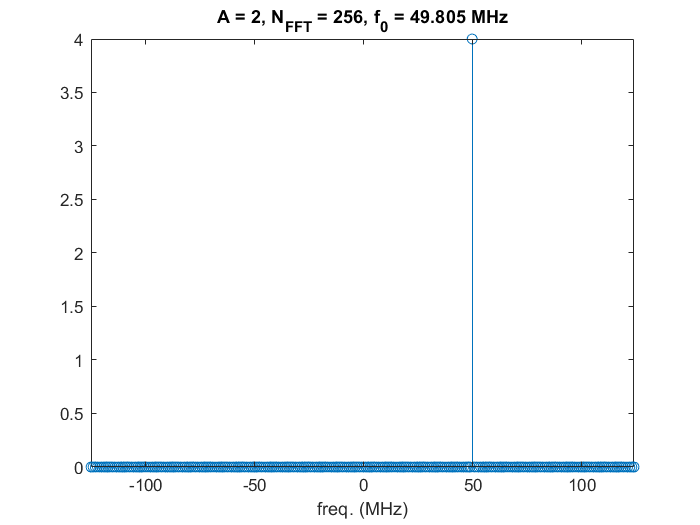

fs = 250*10^6;
ts = 1/fs;
n_fft = 256;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 256, f_0 = 49.805 MHz')

#### Amplitude of Xf is equal to N_FFT *  A. So in order to correct the spectrum we should change Xf to Xf/N_FFT.

#### f.

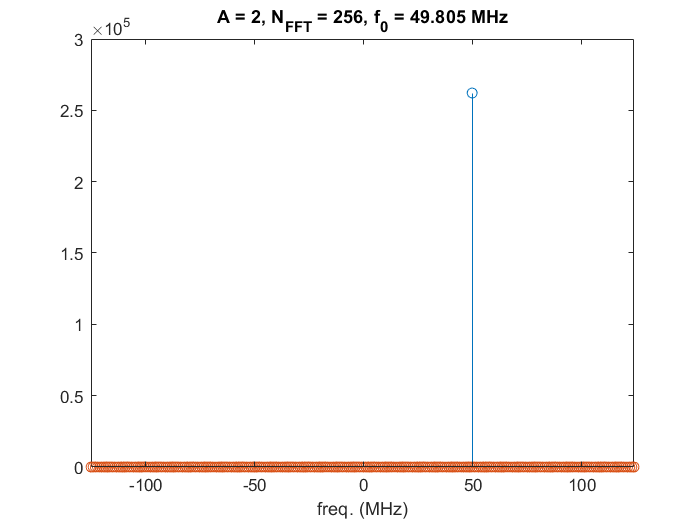

fs = 250*10^6;
ts = 1/fs;
n_fft = 256;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft));
stem(freq, abs(Xf).^2)
hold on
f0 = 250*52/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
hold off
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 256, f_0 = 49.805 MHz')

#### Frequency resolution is propotional to N_FFT. As N_FFT increases the frequency resolution increases as well.

#### g.

fs = 250*10^6;
ts = 1/fs;
n_fft = 256;
A = 2;
n = 0:(n_fft-1);
f0 = 250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft))/n_fft;
time_power = sum(abs(x).^2)/length(x)

time_power = 4

frequency_power = sum(abs(Xf).^2)

frequency_power = 4

#### As we expected, they are equal.

#### h.

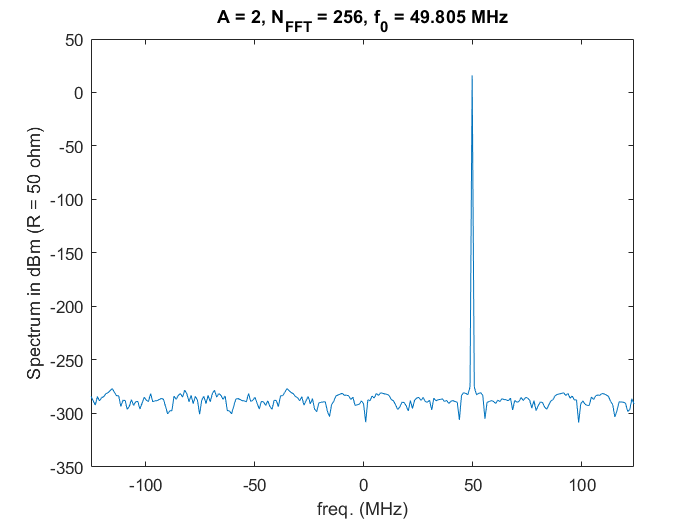

fs = 250*10^6;
ts = 1/fs;
n_fft = 256;
A = 2;
n = 0:(n_fft-1);
freq = ((0:n_fft-1)/n_fft * fs - fs/2)/10^6;
f0 = 250*51/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft))/n_fft;
S_dBm = db(abs(Xf)/sqrt(2), 50) + 30 * ones(1, 256);
plot(freq, S_dBm)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 256, f_0 = 49.805 MHz')
ylabel('Spectrum in dBm (R = 50 ohm)')

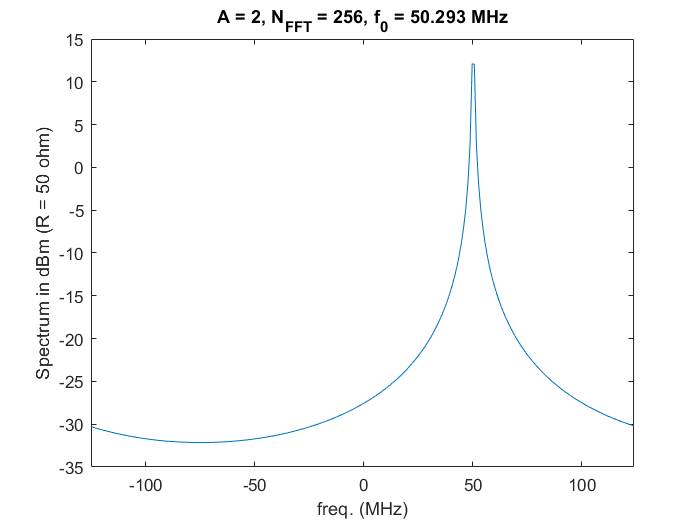



f0 = 250*51.5/256*10^6;
x = A*exp(2*pi*f0.*n*ts*1i);
Xf = fftshift(fft(x, n_fft))/n_fft;
S_dBm = db(abs(Xf)/sqrt(2), 50) + 30 * ones(1, 256);
plot(freq, S_dBm)
xlim([freq(1),freq(end)])
xlabel('freq. (MHz)')
title('A = 2, N_F_F_T = 256, f_0 = 50.293 MHz')
ylabel('Spectrum in dBm (R = 50 ohm)')

#### Part 1: 2) a.

function [y] = dwnsmpl(x, M)
y = zeros(1, fix(length(x)/M));
for i = 1:M:length(x)
    y((i-1)/M + 1) = x(i);
end
end

#### Part 1: 3) a.

function [y] = upsmpl(x, N)
y = zeros(1, (length(x) - 1)*(N - 1) + length(x));
for i = 1:N:(length(x) - 1)*(N - 1) + length(x)
    y(i) = x((i - 1)/N + 1);
end
end

#### Part 2: 2) a.

function [r] = corr_m(x, y)
if length(x) > length(y)
    temp = x;
    x = y;
    y = temp;
end
r = zeros(1, length(y));
for i = 1:length(r)-length(x)
    r(i) = x * conj(y(i:i + length(x) - 1).');
end
end